#  Question1

%(a)
%x1~N(x1,p1)=N([125;125],[10^2 0;0 5^2])
%x2~N(x2,p2)=N([-25;125],[10^2 0;0 5^2])
%x3~N(x3,p3)=N([60;60],[10^2 0;0 5^2])
s1=[0 100]';s2=[100 ,0]';
P_phi=(0.1*pi/180)^2;
h = @(x) dualBearingMeasurement(x, s1, s2);
mean1=[125;125];P1=[10^2 0;0 5^2];N=10000;
mean2=[-25;125];P2=[10^2 0;0 5^2];
mean3=[60;60];P3=[10^2 0;0 5^2];

X1=mvnrnd(mean1,P1,N)';
X2=mvnrnd(mean2,P2,N)';
X3=mvnrnd(mean3,P3,N)';
Y1 = genNonLinearMeasurementSequence(X1, h, P_phi);
[mu_y1, Sigma_y1] = approxGaussianTransform(Y1)

mu_y1 =     0.1986
    1.3742


Sigma_y1 =     0.0017    0.0015
    0.0015    0.0060


Y2 = genNonLinearMeasurementSequence(X2, h, P_phi);
[mu_y2, Sigma_y2] = approxGaussianTransform(Y2)

mu_y2 =     2.3233
    2.3543


Sigma_y2 =     0.0556    0.0103
    0.0103    0.0020


Y3 = genNonLinearMeasurementSequence(X3, h, P_phi);
[mu_y3, Sigma_y3] = approxGaussianTransform(Y3)

mu_y3 =    -0.5968
    2.1540


Sigma_y3 =     0.0101   -0.0116
   -0.0116    0.0154


%(b)
%EKF
disp('****************************************************************************************************')

****************************************************************************************************


[~, ~,EKFmean_y1,EKFP_y1] = nonLinKFupdate(mean1, P1, Y1(:,end), h, P_phi, 'EKF')

EKFmean_y1 =     0.1974
    1.3734


EKFP_y1 = 1.0e-05 *

    0.3041    0.3041
    0.3041    0.3041


[~, ~,EKFmean_y2,EKFP_y2] = nonLinKFupdate(mean2, P2, Y2(:,end), h, P_phi, 'EKF')

EKFmean_y2 =     2.3562
    2.3562


EKFP_y2 = 1.0e-17 *

    0.9992    0.1998
    0.1665    0.0333


[~, ~,EKFmean_y3,EKFP_y3] = nonLinKFupdate(mean3, P3, Y3(:,end), h, P_phi, 'EKF')

EKFmean_y3 =    -0.5880
    2.1588


EKFP_y3 = 1.0e-05 *

    0.3015    0.3015
    0.3015    0.3015


%UKF
disp('****************************************************************************************************')

****************************************************************************************************


[~, ~,UKFmean_y1,UKFP_y1] = nonLinKFupdate(mean1, P1, Y1(:,end), h, P_phi, 'UKF')

UKFmean_y1 =     0.1983
    1.3743


UKFP_y1 =     0.0017    0.0015
    0.0015    0.0059


[~, ~,UKFmean_y2,UKFP_y2] = nonLinKFupdate(mean2, P2, Y2(:,end), h, P_phi, 'UKF')

UKFmean_y2 =     2.3269
    2.3550


UKFP_y2 =     0.0600    0.0108
    0.0108    0.0020


[~, ~,UKFmean_y3,UKFP_y3] = nonLinKFupdate(mean3, P3, Y3(:,end), h, P_phi, 'UKF')

UKFmean_y3 =    -0.5949
    2.1524


UKFP_y3 =     0.0099   -0.0112
   -0.0112    0.0151


%CKF
disp('****************************************************************************************************')

****************************************************************************************************


[~, ~,CKFmean_y1,CKFP_y1] = nonLinKFupdate(mean1, P1, Y1(:,end), h, P_phi, 'CKF')

CKFmean_y1 =     0.1983
    1.3743


CKFP_y1 =     0.0017    0.0015
    0.0015    0.0059


[~, ~,CKFmean_y2,CKFP_y2] = nonLinKFupdate(mean2, P2, Y2(:,end), h, P_phi, 'CKF')

CKFmean_y2 =     2.3265
    2.3550


CKFP_y2 =     0.0566    0.0105
    0.0105    0.0020


[~, ~,CKFmean_y3,CKFP_y3] = nonLinKFupdate(mean3, P3, Y3(:,end), h, P_phi, 'CKF')

CKFmean_y3 =    -0.5948
    2.1523


CKFP_y3 =     0.0096   -0.0112
   -0.0112    0.0150


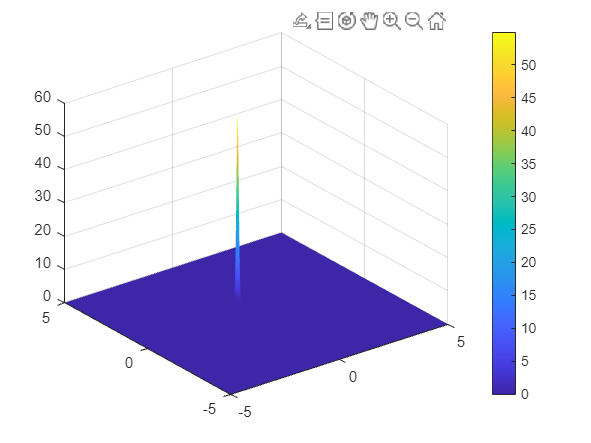

%(c)
x_plot=-5:0.01:5;
y_plot=-5:0.01:5;
[X,Y]=meshgrid(x_plot,y_plot);
figure(1)
p=mvnpdf([X(:),Y(:)],mu_y1', Sigma_y1);
P=reshape(p,size(X)); % 求取联合概率密度
figure(2)
surf(X,Y,P)
shading interp
colorbar

%question2
%question3

# normPlot function

function [x,Y]=normPlot(value,mu,variance)
%GENLINEARSTATESEQUENCE generates an N-long sequence of states using a 
%    Gaussian prior and a linear Gaussian process model
%
%Input:
%   mu         mean
%   X_true     true value of X
%   X_estimate          estimate value from kalman filter
%   variance=(X_true(:,k+1)-X_estimate(:,k))^2;
%   k           sample time
%   value       domain 
%
%Output:
%   Y           normpdf of Y
x=[mu-value:0.01:mu+value];
Y=normpdf(x,mu,sqrt(variance));
end

# approxGaussian function

function [mu_y, Sigma_y] = approxGaussianTransform(data)
N=length(data);
mu_y=mean(data,2);
Sigma_y=(data-mu_y)*(data-mu_y)'/(N-1);
end

# Functions for nonlinear kalman

# HA3.1.1 Coordinated turn motion model

function [fx, Fx] = coordinatedTurnMotion(x, T)
%COORDINATEDTURNMOTION calculates the predicted state using a coordinated
%turn motion model, and also calculated the motion model Jacobian
%
%Input:
%   x           [5 x 1] state vector
%   T           [1 x 1] Sampling time
%
%Output:
%   fx          [5 x 1] motion model evaluated at state x
%   Fx          [5 x 5] motion model Jacobian evaluated at state x
%
% NOTE: the motion model assumes that the state vector x consist of the
% following states:
%   px          X-position
%   py          Y-position
%   v           velocity
%   phi         heading
%   omega       turn-rate

% Your code for the motion model here
fx =[x(1)+T*x(3)*cos(x(4));x(2)+T*x(3)*sin(x(4));x(3);x(4)+T*x(5);x(5)];

%Check if the Jacobian is requested by the calling function
if nargout > 1
    % Your code for the motion model Jacobian here
    % Fx = ...
    Fx=eye(5);
    Fx(1:2,3:4)=[T*cos(x(4)) -T*x(3)*sin(x(4));T*sin(x(4)) T*x(3)*cos(x(4))];
    Fx(4,5)=T;
end

end


# HA3.1.2 Dual Bearing Measurement Model


function [hx, Hx] = dualBearingMeasurement(x, s1, s2)
%DUOBEARINGMEASUREMENT calculates the bearings from two sensors, located in 
%s1 and s2, to the position given by the state vector x. Also returns the
%Jacobian of the model at x.
%
%Input:
%   x           [n x 1] State vector, the two first element are 2D position
%   s1          [2 x 1] Sensor position (2D) for sensor 1
%   s2          [2 x 1] Sensor position (2D) for sensor 2
%
%Output:
%   hx          [2 x 1] measurement vector
%   Hx          [2 x n] measurement model Jacobian
%
% NOTE: the measurement model assumes that in the state vector x, the first
% two states are X-position and Y-position.

% Your code here
n=size(x,1);
y1=x(2,:)-s1(2);
y2=x(2,:)-s2(2);
x1=x(1,:)-s1(1);
x2=x(1,:)-s2(1);
hx=[atan2(y1,x1);
    atan2(y2,x2)];
    
Hx =[-y1/(x1^2+y1^2),x1/(x1^2+y1^2),zeros(1,n-2);
    -y2/(x2^2+y2^2),x2/(x2^2+y2^2),zeros(1,n-2)];
end


# HA3.1.3 Generate non-linear state sequence

function X = genNonLinearStateSequence(x_0, P_0, f, Q, N)
%GENNONLINEARSTATESEQUENCE generates an N+1-long sequence of states using a 
%    Gaussian prior and a nonlinear Gaussian process model
%
%Input:
%   x_0         [n x 1] Prior mean
%   P_0         [n x n] Prior covariance
%   f           Motion model function handle
%               [fx,Fx]=f(x) 
%               Takes as input x (state), 
%               Returns fx and Fx, motion model and Jacobian evaluated at x
%               All other model parameters, such as sample time T,
%               must be included in the function
%   Q           [n x n] Process noise covariance
%   N           [1 x 1] Number of states to generate
%
%Output:
%   X           [n x N+1] State vector sequence
%

% Your code here
X0= mvnrnd(x_0, P_0)';
X=X0;
% fx=f(:,1)
% Fx=f(:,2:end)
for i=1:N
    q=mvnrnd(zeros(length(x_0),1), Q)';
    X=[X f(X(:,i))+q];
end

end


# HA3.1.4 Generate non-linear measurements

function Y = genNonLinearMeasurementSequence(X, h, R)
%GENNONLINEARMEASUREMENTSEQUENCE generates ovservations of the states 
% sequence X using a non-linear measurement model.
%
%Input:
%   X           [n x N+1] State vector sequence
%   h           Measurement model function handle
%   h           Measurement model function handle
%               [hx,Hx]=h(x) 
%               Takes as input x (state) 
%               Returns hx and Hx, measurement model and Jacobian evaluated at x
%   R           [m x m] Measurement noise covariance
%
%Output:
%   Y           [m x N] Measurement sequence
%

% Your code here
Y=[];
for i=2:length(X)
    Y=[Y, h(X(:,i))+mvnrnd(zeros(length(R),1),R)'];
end
end


# HA3.1.5 Compute sigma points

function [SP,W] = sigmaPoints(x, P, type)
% SIGMAPOINTS computes sigma points, either using unscented transform or
% using cubature.
%
%Input:
%   x           [n x 1] Prior mean
%   P           [n x n] Prior covariance
%
%Output:
%   SP          [n x 2n+1] UKF, [n x 2n] CKF. Matrix with sigma points
%   W           [1 x 2n+1] UKF, [1 x 2n] UKF. Vector with sigma point weights 
%
n=length(x);
sqrtP=sqrtm(P);
    switch type        
        case 'UKF'
        SP=zeros(n,2*n+1);
        W=zeros(1,2*n+1);
        W(:,1)=1-n/3;
        SP(:,1)=x;
        for i=1:n
            W(:,i+1)=(1-W(:,1))/(2*n);
            W(:,n+i+1)=(1-W(:,1))/(2*n);
            SP(:,i+1)=x+sqrt(n/(1-W(:,1)))*sqrtP(:,i);
            SP(:,i+n+1)=x-sqrt(n/(1-W(:,1)))*sqrtP(:,i);
        end
            % your code     
        case 'CKF'
        SP=zeros(n,2*n);
        W=zeros(1,2*n);  
            % your code
        for i=1:n
            W(:,i)=1/(2*n);
            W(:,i+n)=1/(2*n);
            SP(:, i) = x+sqrt(n)*sqrtP(:,i);
            SP(:, i+n) = x-sqrt(n)*sqrtP(:,i);
        end
        otherwise
            error('Incorrect type of sigma point')
    end

end


# HA3.1.6 Non-linear Kalman prediction

function [x, P] = nonLinKFprediction(x, P, f, Q, type)
%NONLINKFPREDICTION calculates mean and covariance of predicted state
%   density using a non-linear Gaussian model.
%
%Input:
%   x           [n x 1] Prior mean
%   P           [n x n] Prior covariance
%   f           Motion model function handle
%               [fx,Fx]=f(x) 
%               Takes as input x (state), 
%               Returns fx and Fx, motion model and Jacobian evaluated at x
%               All other model parameters, such as sample time T,
%               must be included in the function
%   Q           [n x n] Process noise covariance
%   type        String that specifies the type of non-linear filter
%
%Output:
%   x           [n x 1] predicted state mean
%   P           [n x n] predicted state covariance
n=length(x);

    switch type
        case 'EKF'
           [fx,Fx]=f(x);
            x_before=x;
            P_before=P;
            % Your EKF code here
            x=fx;
            P=Fx*P_before*Fx'+Q;   
        case 'UKF'
            % Your UKF code here
            [SP,W] = sigmaPoints(x, P, 'UKF');
%             [fx,Fx]=f(SP);
            x=zeros(n,1);P=zeros(n,n);
            f_pred = zeros(n, length(W));
            for i=1:length(W)
                f_pred(:,i) = f(SP(:,i));
                x=x+f_pred(:,i)*W(i);
            end
            for i=1:length(W)
                P=P+(f_pred(:,i)-x)*(f_pred(:,i)-x)'*W(i);
            end
             P=P+Q
            % Make sure the covariance matrix is semi-definite
            if min(eig(P))<=0
                [v,e] = eig(P, 'vector');
                e(e<0) = 1e-4;
                P = v*diag(e)/v;
            end
                
        case 'CKF'
            
            % Your CKF code here
            [SP,W] = sigmaPoints(x, P, 'CKF');
%             [fx,Fx]=f(SP);
            x=zeros(n,1);P=zeros(n,n);
            f_pred = zeros(n, length(W));
            for i=1:length(W)
                f_pred(:,i) = f(SP(:,i));
                x=x+f_pred(:,i)*W(i);
            end
            for i=1:length(W)
                P=P+(f_pred(:,i)-x)*(f_pred(:,i)-x)'*W(i);
            end
            P=P+Q;
        otherwise
            error('Incorrect type of non-linear Kalman filter')
    end

end


# HA3.1.7 Nonlinear Kalman update


function [x, P,y_minus,Pyy] = nonLinKFupdate(x, P, y, h, R, type)
%NONLINKFUPDATE calculates mean and covariance of predicted state
%   density using a non-linear Gaussian model.
%
%Input:
%   x           [n x 1] Prior mean
%   P           [n x n] Prior covariance
%   y           [m x 1] measurement vector
%   h           Measurement model function handle
%               [hx,Hx]=h(x) 
%               Takes as input x (state), 
%               Returns hx and Hx, measurement model and Jacobian evaluated at x
%               Function must include all model parameters for the particular model, 
%               such as sensor position for some models.
%   R           [m x m] Measurement noise covariance
%   type        String that specifies the type of non-linear filter
%
%Output:
%   x           [n x 1] updated state mean
%   P           [n x n] updated state covariance
%
    n=length(x);
    m=length(y);
    switch type
        
        case 'EKF'
%             [x, P] = nonLinKFprediction(x, P, f, Q, 'EKF')
            [hx,Hx]=h(x);
            S=Hx*P*Hx'+R;
            KK=P*Hx'*inv(S);
            x=x+KK*(y-hx);
            P=P-KK*S*KK';
            y_minus=hx;
            Pyy=Hx*P*Hx';
            % Your EKF update here
            
        case 'UKF'
    
            % Your UKF update here
            [SP,W] = sigmaPoints(x, P, 'UKF');
            y_minus=zeros(m,1);Pxy=zeros(n,m);Pyy=zeros(m,m);
            y_pred = zeros(m, length(W));
            S=R;
            for i=1:length(W)
                y_pred(:,i)= h(SP(:,i));
                y_minus=y_minus+y_pred(:,i)*W(i);
            end
            for i=1:length(W)
                Pxy=Pxy+(SP(:,i)-x)*(y_pred(:,i)-y_minus)'*W(i);
                Pyy=Pyy+(y_pred(:,i)-y_minus)*(y_pred(:,i)-y_minus)'*W(i);
                S=S+(y_pred(:,i)-y_minus)*(y_pred(:,i)-y_minus)'*W(i);
            end
            x=x+Pxy*inv(S)*(y-y_minus);
            P=P-Pxy*inv(S)*Pxy';
            % Make sure the covariance matrix is semi-definite
            if min(eig(P))<=0
                [v,e] = eig(P, 'vector');
                e(e<0) = 1e-4;
                P = v*diag(e)/v;
            end
            
        case 'CKF'
    
            % Your CKF update here
            [SP,W] = sigmaPoints(x, P, 'CKF');
            y_minus=zeros(m,1);Pxy=zeros(n,m);Pyy=zeros(m,m);
            y_pred = zeros(m, length(W));
            S=R;
            for i=1:length(W)
                [y_pred(:,i),~] = h(SP(:,i));
                y_minus=y_minus+y_pred(:,i)*W(i);
            end
            for i=1:length(W)
                Pxy=Pxy+(SP(:,i)-x)*(y_pred(:,i)-y_minus)'*W(i);
                Pyy=Pyy+(y_pred(:,i)-y_minus)*(y_pred(:,i)-y_minus)'*W(i);
                S=S+(y_pred(:,i)-y_minus)*(y_pred(:,i)-y_minus)'*W(i);
            end
            x=x+Pxy*inv(S)*(y-y_minus);
            P=P-Pxy*inv(S)*Pxy';
        otherwise
            error('Incorrect type of non-linear Kalman filter')
    end

end

# HA3.1.8 Non-linear Kalman filter


function [xf, Pf, xp, Pp] = nonLinearKalmanFilter(Y, x_0, P_0, f, Q, h, R, type)
%NONLINEARKALMANFILTER Filters measurement sequence Y using a 
% non-linear Kalman filter. 
%
%Input:
%   Y           [m x N] Measurement sequence for times 1,...,N
%   x_0         [n x 1] Prior mean for time 0
%   P_0         [n x n] Prior covariance
%   f                   Motion model function handle
%                       [fx,Fx]=f(x) 
%                       Takes as input x (state) 
%                       Returns fx and Fx, motion model and Jacobian evaluated at x
%   Q           [n x n] Process noise covariance
%   h                   Measurement model function handle
%                       [hx,Hx]=h(x,T) 
%                       Takes as input x (state), 
%                       Returns hx and Hx, measurement model and Jacobian evaluated at x
%   R           [m x m] Measurement noise covariance
%
%Output:
%   xf          [n x N]     Filtered estimates for times 1,...,N
%   Pf          [n x n x N] Filter error convariance
%   xp          [n x N]     Predicted estimates for times 1,...,N
%   Pp          [n x n x N] Filter error convariance
%

% Your code here. If you have good code for the Kalman filter, you should re-use it here as
% much as possible.
N=size(Y,2);
m = size(Y,1);
n = length(x_0);
xf=zeros(n,N);Pf=zeros(n,n,N);xp=zeros(n,N);Pp=zeros(n,n,N);
for i=1:N
    [x_predict, P_predict] = nonLinKFprediction(x_0, P_0, f, Q, type);
    xp(:,i)=x_predict;
    Pp(:,:,i)=P_predict;
    [x_0, P_0] = nonLinKFupdate(x_predict, P_predict, Y(:,i), h, R, type);
    xf(:,i)=x_0;
    Pf(:,:,i)=P_0;
end
end